**Data**

x1 = [1 1 1 2 2 2 3 3 3]';

x2 = [1 2 3 1 2 3 1 2 3]';

y = [10.5 13.9 15.1 11.5 14.7 18.9 14.2 18.5 20.1]';

**Plot data**

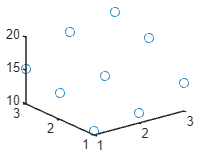

plot3(x1,x2,y,'o')

**Create Z matrix**

z = [ones(9,1) x1 x2]

z =      1     1     1
     1     1     2
     1     1     3
     1     2     1
     1     2     2
     1     2     3
     1     3     1
     1     3     2
     1     3     3


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =     4.8667
    2.2167
    2.9833


**Plot data and the best fitted curve**

xx1 = 1 : 0.2 : 3

xx1 =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


xx2 = 1 : 0.2 : 3

xx2 =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000



yy = a(1) + a(2).*xx1 + a(3).*xx2

yy =    10.0667   11.1067   12.1467   13.1867   14.2267   15.2667   16.3067   17.3467   18.3867   19.4267   20.4667


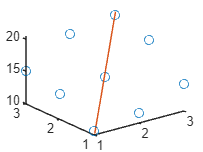


plot3(x1,x2,y,'o',xx1,xx2,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 4.3967

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 87.2800

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.9496

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr/(length(x1)-(length(a)+1)))

syx = 0.9377

**Predict the value of y for the given x**

xtest1 = 1.5;
xtest2 = 1.5;

predict_y = 12.6667

predict_y = a(1) + a(2).*xtest1 + a(3).*xtest2